# ***Chapter 9 - Change Detection***

## *Section A: Outlier Detection: Quantile Regression*

How to tell a new observation is indeed an outlier? It's intuitive to use an out-of-bound z-score to indicate the existence of an outlier for a general financial time series. Indeed, this is based on the assumptions of linear regression setting. Quantile regression provides another approach for outlier detection without the need for assuming Gaussian distribution for the regression residuals.

**Linear Regression **The model structure is: $y_t=\mathbf{\beta}'\mathbf{x}_t+\epsilon_t$, where $\epsilon_t{\tilde}N(0,\sigma^2)$ for all $t$. At time $t+1$, the observation $y_{t+1}$ is possibly an outlier if $|\frac{y_{t+1}-\hat{\beta'}x_{t+1}}{\hat{\sigma}}|\geq z^*$, where $z^*$ is a threshold value depending on the confidence level, usually set to 2.

**Quantile Regression **Instead of assuming i.i.d. normal distribution for residuals and aiming to estimate the mean of the dependent variable, quantile regression assumes a linear relationship between predictors ($X$) and the quantile values of the distribution of the dependent variable ($Y$). Compared to linear regression, it has the following advantages:

- It allows us to study the impact of predictors on diﬀerent quantiles of the response distribution, and thus provides a complete picture of the relationship between $Y$ and 

- It is robust to outliers in y observations

- The estimation and inference are distribution-free.

*Definition of Quantile**: *Let Y be a random variable with cumulative distribution function CDF $F_Y(y)=P(Y\leq y)$. The $\tau$-th quantile of Y is$Q_{\tau}(Y)={inf}\{y:F_Y(y)\geq \tau\}$.

*Assumption for Quantile Regression**: *$Q_{\tau}(Y|X=\mathbf{x})=\mathbf{\beta}(\tau) ' \mathbf{x}$, i.e., conditional on predictor observations $\mathbf{x}$, the $\tau$-th quantile of the distribution of $Y$ is a linear function of $\mathbf{x}$.

*Lemma*: for any random variable $Y$, $Q_{\tau}(Y)=\arg \min\limits_a E[\rho_{\tau}(Y-a)]$, where $\rho_{\tau}(u)=u\cdot(\tau-1_{u<0})$. (note: $1_{u<0}=1$ if $u<0$, otherwise 0).

Suppose we observe a random sample $\{y_t,\mathbf{x}_t: t=1,...,T\}$,  for a given $\tau$  where $\tau\in(0,1)$, we can solve for $\mathbf{\beta}(\tau)$ as follows:$\hat{\mathbf{\beta}}(\tau)=\arg \min\limits_{\mathbf{\beta}}\sum\limits_{t=1}^T\rho_{\tau}(y_t-\mathbf{\beta}'\mathbf{x}_t)$.

Comments: 

- when $\tau=0.5$, $Q_{0.5}(Y)=\arg \min\limits_a E|Y-a|$, which solves for the distribution median of $Y$, and the quantile regression coefficient estimate $\mathbf{\beta}(0.5)$ can be obtained by solving: $ \min\limits_{\mathbf{\beta}}\sum\limits_{t=1}^T|y_t-\mathbf{\beta}'\mathbf{x}_t|$.

- linear programming is applicable to locate the solution of $\hat{\mathbf{\beta}}(\tau)$.

%   simulate a time series with outliers
%   y=0.1*t+5*sin(t)+\epsilon
T=100;
rng(0);
x_vec=[1:T]';
X=[x_vec,sin(x_vec)];
beta_ols=[0.1,5]';
epsilon=randn(T,1);
Y=X*beta_ols+epsilon;

%   regression without outliers
regress(Y,X)

ans =     0.1001
    4.9853


%   outlier's positions
outlier_pos=[floor(T/4),T-40];
Y(outlier_pos)=X(outlier_pos,:)*[0.3,5]';

%   linear regression with outliers
regress(Y,X)

ans =     0.1023
    4.9121


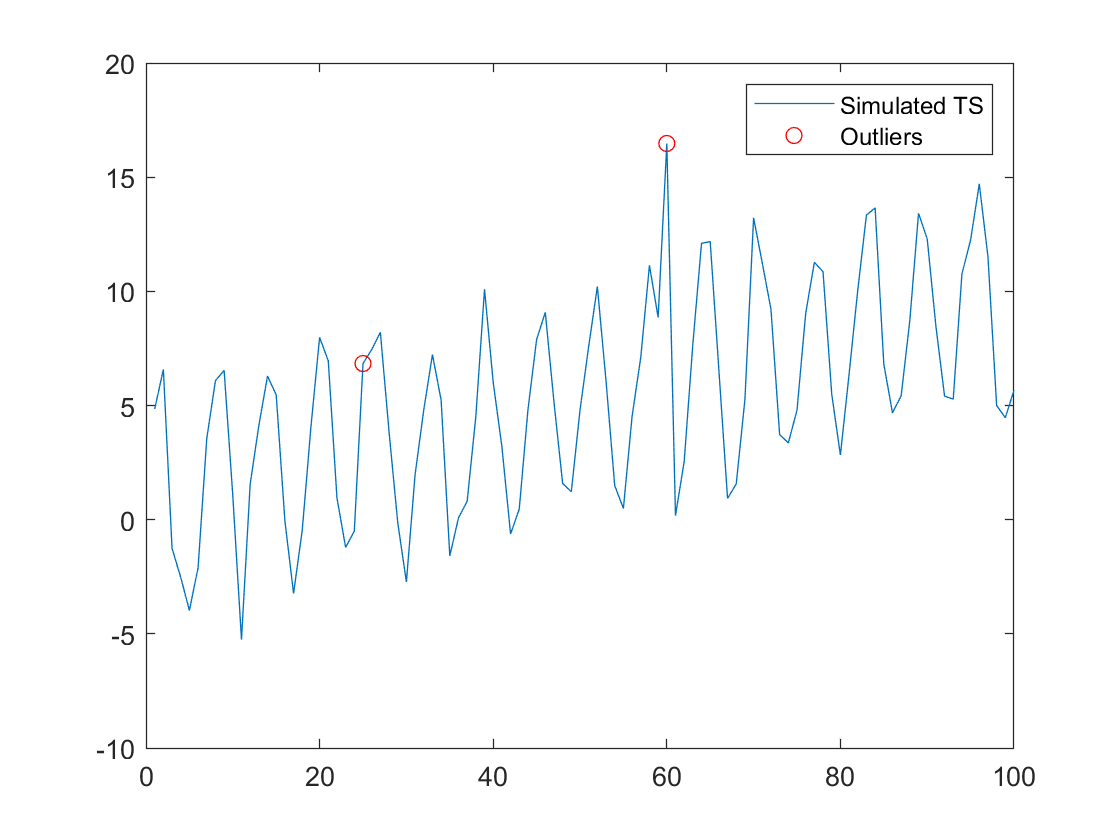

%   plot the time series
figure
pp(1)=plot(x_vec,Y);
hold on
pp(2)=plot(x_vec(outlier_pos),Y(outlier_pos),'or');
legend(pp,{'Simulated TS','Outliers'});

%   let's run rolling window regressions to test outlier detection
lb_window=12;

%   calculate the +2 and -2 sigma bounds based on linear regressions
Zbound=nan(T,2);

%   calculate 5-th and 95-th quantiles based on quantile regressions
Qbound=nan(T,2);


for t=lb_window+1:T
   
    y=Y(t-lb_window:t-1);
    x=X(t-lb_window:t-1,:);
    
    %%%%%
    %   run linear regression based on the previous observations
    [b,bint,r] = regress(y,x);
    
    %   standard deviation of residuals
    tmp_sigma=nanstd(r);
    
    %   current forecasts based on linear regression model
    Zbound(t,1)=X(t,:)*b+1.96*tmp_sigma;
    Zbound(t,2)=X(t,:)*b-1.96*tmp_sigma;
    
    %%%%%
    %    run quantile regression 
    tau=0.975;
    rho=@(r)sum(abs(r.*(tau-(r<0))));
    p1=fminsearch(@(p)rho(y-x*p),b);
    Qbound(t,1)=X(t,:)*p1;
    
    tau=0.025;
    rho=@(r)sum(abs(r.*(tau-(r<0))));
    p2=fminsearch(@(p)rho(y-x*p),b);
    Qbound(t,2)=X(t,:)*p2;
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.610049 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.334655 



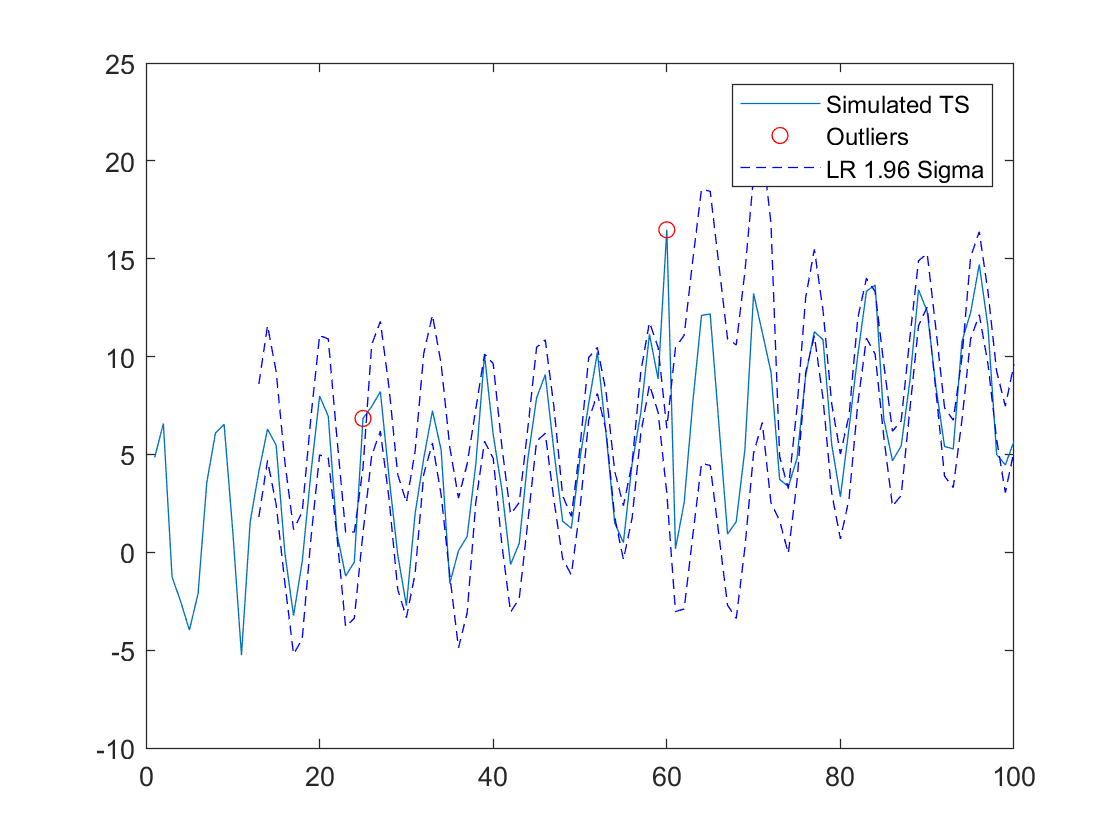

%   plot the time series
figure
pp(1)=plot(x_vec,Y);
hold on
pp(2)=plot(x_vec(outlier_pos),Y(outlier_pos),'or');
pp(3)=plot(x_vec,Zbound(:,1),'--b');
plot(x_vec,Zbound(:,2),'--b');
legend(pp,{'Simulated TS','Outliers','LR 1.96 Sigma'});

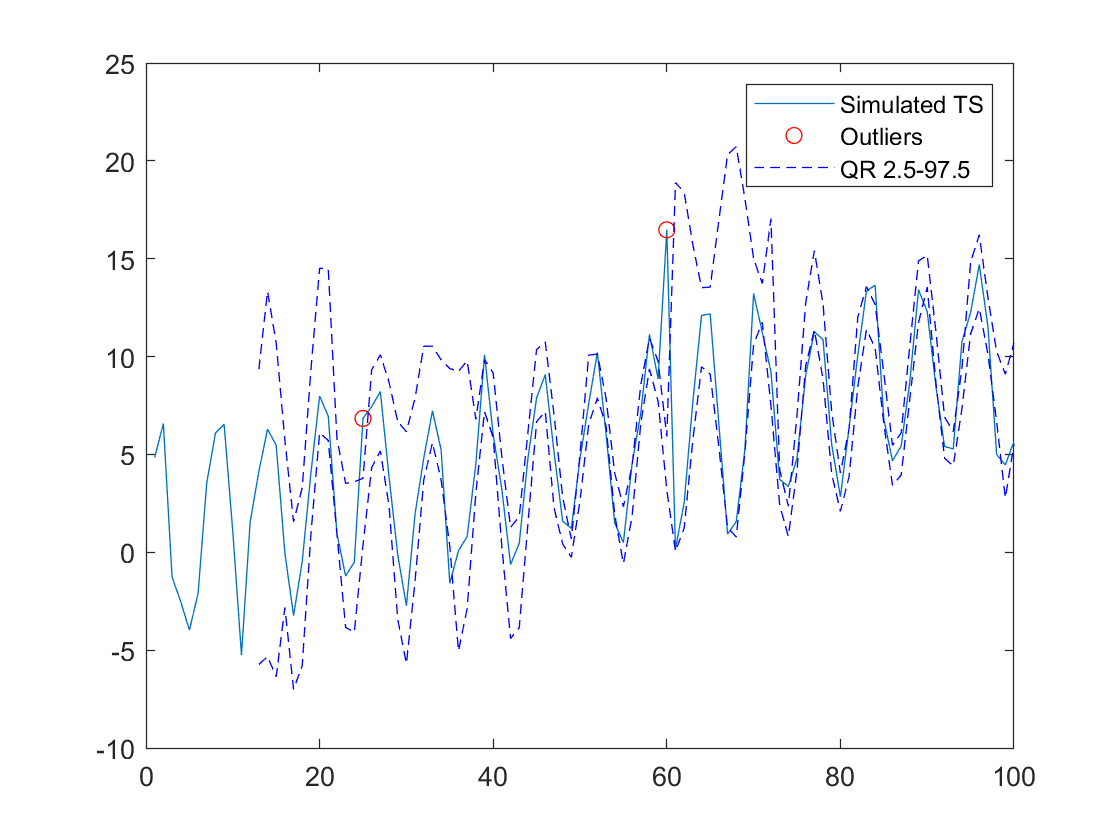

%   plot the time series
figure
pp(1)=plot(x_vec,Y);
hold on
pp(2)=plot(x_vec(outlier_pos),Y(outlier_pos),'or');
pp(3)=plot(x_vec,Qbound(:,1),'--b');
plot(x_vec,Qbound(:,2),'--b');

legend(pp,{'Simulated TS','Outliers','QR 2.5-97.5'});

## *Section B: Structural Change: Chow Test and Cusum Test*

Structural break can occur when there is a change of relationship for data being examined. For instance, technology advancement has dramatically increased the productivity for a man-hour; a central bank's monetary policy changes may introduce new factors in risk pricing. If a relationship can always be uncovered by linear regression, detecting structural break point is equivalent of finding a point where data raltionships before and after that point are significant different from each other, i.e., two separate linear regressions for the two subsets of data separately are more appropriate than a single linear regression for the whole data set. [Chow Test](https://en.wikipedia.org/wiki/Chow_test) is a variation of F-test for the task of detecting such structural break. 

***Chow Test ***

**Step 1 -** Determine the structure of a linear regression model: $y_t=\mathbf{\beta}'\mathbf{x}_t+\epsilon_t$ where $\mathbf{x}_t$ is a vector of independent variables, and $\mathbf{\beta}$ is the coefficient vector. Let's denote $k=|\mathbf{\beta}|$, i.e., the number of parameters for this model. We'll assume the error terms are i.i.d. normally distributed with unknown variance.

**Step 2 -** Suppose we know $t^*$ is the structural break point, we need to run the following three regressions:

- Run the model for the whole data set: $y_t=\mathbf{\beta_{0}}'\mathbf{x}_t+\epsilon_t$. The sum of squared errors: $S_0={\sum_{t=1}^T} (y_t-\mathbf{\beta}_0'\mathbf{x}_t)^2$.

- Run the model for the first part of the data set, i.e., for $t\leq t^*$: $y_t=\mathbf{\beta_1}'\mathbf{x}_t+\epsilon_t$. The sum of squared errors: $S_1={\sum_{t\leq t^*}} (y_t-\mathbf{\beta}_1'\mathbf{x}_t)^2$. Assuming there are $N_1$ data points for $t\leq t^*$.

- Run the model for the second part of the data set, i.e.,for $t>t^*$: $y_t=\mathbf{\beta_2}'\mathbf{x}_t+\epsilon_t$. The sum of squared errors: $S_2={\sum_{t> t^*}} (y_t-\mathbf{\beta}_2'\mathbf{x}_t)^2$. Assuming there are $N_2$ data points for $t> t^*$.

**Step 3 - **The null hypothesis of the Chow Test: $\mathbf{\beta_1}=\mathbf{\beta_2}$. Under the null hypothesis, the Chow Test statistics has the form:

$F=\frac{(S_0-S_1-S_2)/k}{(S_1+S_2)/(N_1+N_2-2k)}$,

where the test stat $F$follows the F distribution with $(k,N_1+N_2-2k)$ degrees of freedom. 

**Step 4 - **Find the critical value from the F table and reject the null hypothesis if the value of $F$ falls into the rejection region, when $F$ is greater than the critical value. If the null hypothess is rejected, we can claim with a certain confidence level that $t^*$ is indeed a structural break point from Chow Test. 

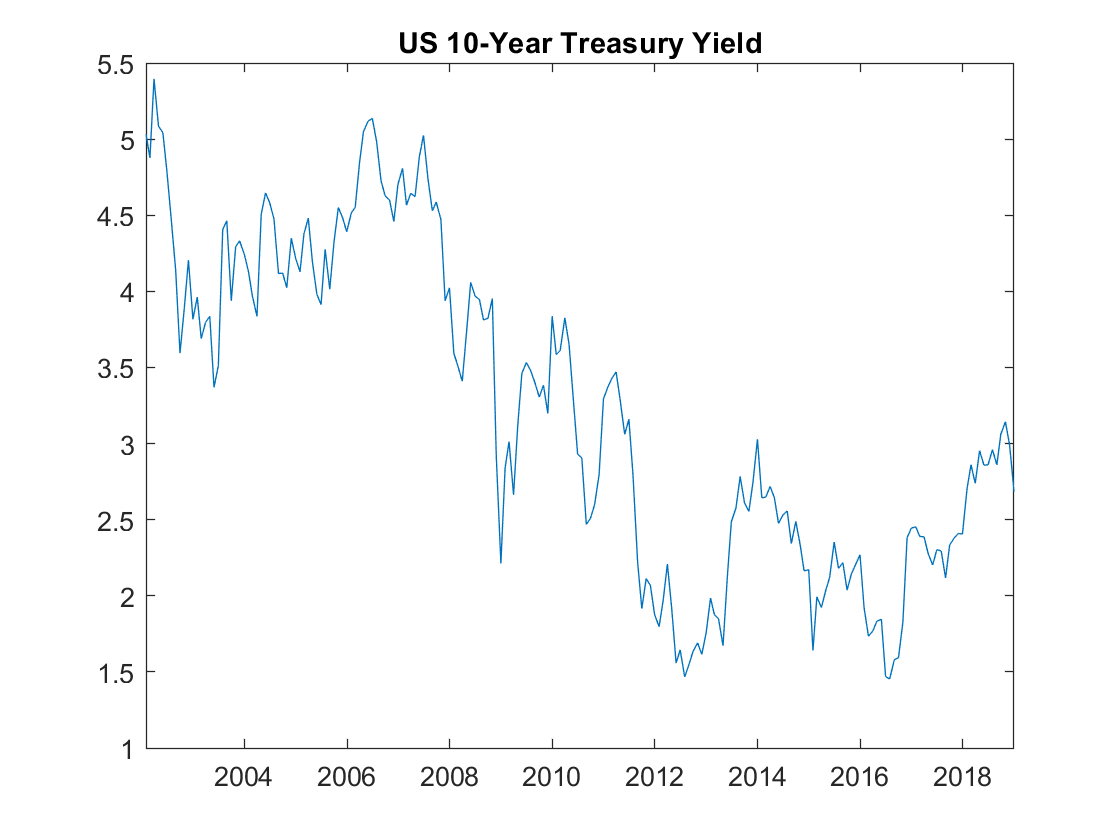

%%%%%% An Example of Running Chow-Test %%%%%%%%%%%%%
filenm='DataSource.xlsx';
shnm='USTY10';
[blah,blah,rawraw]=xlsread(filenm,shnm);

%   tradays and the corresponding US 10-Year Treasury bond yields
tradays=rawraw(2:end,1);
us10y=cell2mat(rawraw(2:end,2));

%   valid data only
valid_pos=~isnan(us10y);
tradays=datenum(tradays(valid_pos));
us10y=us10y(valid_pos);

%   re-order the data
[blah,order]=sort(tradays,'ascend');
tradays=tradays(order);
us10y=us10y(order);

%   plot the historical yield movements
plot(datetime(datevec(tradays)),us10y)
title('US 10-Year Treasury Yield');

%   Let's use the intercept-only linear regression model, y_t=c+\epsilon_t
%   and run Chow Test to test if 2007/12/31 is a structural break point 

%   there is only one parameter for this model
k=1;

%   the independent variable vector
y=us10y;

%%%%%
%   run the intercept-only regression for all the data points
[b,bint,r] = regress(y,ones(length(y),1)) ;

%   calculate the sum of squared erros/residuals
S0=sum(r.^2);

%%%%%
%   locate the position of the potential structural break point
t_star=find(tradays<=datenum(2007,12,31),1,'last');

%   run the regression for the first part
y=us10y(1:t_star);
[~,bint,r] = regress(y,ones(length(y),1)) ;

%   the SSE 
S1=sum(r.^2);
N1=length(y);

%   run the regression for the second part
y=us10y(t_star+1:end);
[b,bint,r] = regress(y,ones(length(y),1)) ;

%   the SSE 
S2=sum(r.^2);
N2=length(y);

%%%%%%
%   calculate the F stat for the Chow Test
F=((S0-S1-S2)/k)/((S1+S2)/(N1+N2-2*k))

F = 431.9936


%   find out the critical value for F-distribution
%   with degrees of freedom (k,N1+N2-2k)
F_critical=finv(0.95,k,N1+N2-2*k)

F_critical = 3.8879

%   calculate the p value
p_val=1-fcdf(F,k,N1+N2-2*k)

p_val = 0

%%%%%%%%%%%%%%%%%%%%%
%  Fortunately: Matlab has the function chowtest() ready for implementation
%   note: we don't need the function to add an additional intercept 
[h,pValue,stat,cValue] = chowtest(ones(length(us10y),1),us10y,t_star,'Intercept',false)

h = logical
   1


pValue = 4.5810e-52

stat = 431.9936

cValue = 3.8879

%   let's check if 2016/12/31 is a structural break point for all yields
%   after 2007/12/31
us10y_p2=us10y(t_star+1:end);
t_star2=find(tradays(t_star+1:end)<=datenum(2016,12,31),1,'last');
[h,pValue,stat,cValue] = chowtest(ones(length(us10y_p2),1),us10y_p2,t_star2,'Intercept',false)

h = logical
   0


pValue = 0.8235

stat = 0.0500

cValue = 3.9140

One can iteratively apply Chow tests to locate all candidate structural break points along time line.

***Cusum (Cumulative Summation) Test ***

Cusum test, which indeed includes two tests (will see below), is another commonly-used method to study the stability over time of regression relationships. Statistics based on cusum of recursive residuals and cusum of squared recursive resdiuals are used in the test for evaluating constancy of coefficient parameters. Details of the test construction please see the paper:

Brown, R. L., J. Durbin, and J. M. Evans. “Techniques for Testing the Constancy of Regression Relationships Over Time.” *Journal of the Royal Statistical Society, Series B*. Vol. 37, 1975, pp. 149–192.

In the following, we introduce the test settings and the main results of Cusum Tests.

The basic model to be considered is: 

$y_t=\mathbf{\beta}_t'\mathbf{x}_t+\epsilon_t$, for $t=1,...,T$,

where we assume $\mathbf{x}_t$ is the column vector of $k$ regressors (note: if intercept is included, the first element is always unity), and the error terms $\epsilon_t$ are i.i.d. following normal distribution $N(0,\sigma_t^2)$.  The $k\times1$ column vector of coefficient parameters $\mathbf{\beta}_t$ has a subscript t indicating it may vary with time, so does the error variance term $\sigma_t^2$. Given the above settings, the (null) hypothesis $H_0$ of constancy over time is: 

- 
$$\mathbf{\beta}_1=\mathbf{\beta}_2=\cdots=\mathbf{\beta}_T=\mathbf{\beta}$$


- 
$$\sigma_1^2=\sigma_2^2=\cdots=\sigma_T^2=\sigma^2$$


Under the hypothesis $H_0$, let's denote $\mathbf{b}_r$ as the estimate of $\mathbf{\beta}$ when based on the first $r$ observation paris, i.e., $\{(\mathbf{x}_t,y_t): t=1,...,r\}$. The OLS estimate $\mathbf{b}_r$ has the representation: $\mathbf{b}_r=(\mathbf{X'}_r\mathbf{X}_r)^{-1}\mathbf{X'}_r\mathbf{Y}_r$, where the $r\times k$ matrix $\mathbf{X}_r=[\mathbf{x}_1,...,\mathbf{x}_r]'$ , and the $r\times 1$ vector $\mathbf{Y}_r=[y_1,...,y_r]'$. Note: we'll start with $r\geq k$ so that the number of observations ($r$) is at least as many as the number of model paramters.

Definitions:

- *Recursive residuals*: $w_r=\frac{y_r-\mathbf{x'}_r\mathbf{b}_{r-1}}{\sqrt{1+\mathbf{x'}_r(\mathbf{X'}_{r-1}\mathbf{X}_{r-1})^{-1}\mathbf{x}_r}}$, for $r=k+1,...,T$.

- *Residual sum of squares*: $S_r=(\mathbf{Y}_r-\mathbf{X}_r\mathbf{b}_r)'(\mathbf{Y}_r-\mathbf{X}_r\mathbf{b}_r)$, for $r=k,...,T$.

Property of recursive residuals: under $H_0$, $w_{k+1},...,w_T$ are independent random variables with normal distribution of $N(0,\sigma^2)$.

Other observations, or for $r=k+1,...,T$, we have the following recursive formulas:

- 
$$(\mathbf{X'}_r\mathbf{X}_r)^{-1}=(\mathbf{X'}_{r-1}\mathbf{X}_{r-1})^{-1}-\frac{(\mathbf{X'}_{r-1}\mathbf{X}_{r-1})^{-1}\mathbf{x}_r\mathbf{x'}_r(\mathbf{X'}_{r-1}\mathbf{X}_{r-1})^{-1}}{1+\mathbf{x'}_r(\mathbf{X'}_{r-1}\mathbf{X}_{r-1})^{-1}\mathbf{x}_r}$$


- 
$$\mathbf{b}_r=\mathbf{b}_{r-1}+(\mathbf{X'}_r\mathbf{X}_r)^{-1}\mathbf{x}_r(y_r-\mathbf{x'}_r\mathbf{b}_{r-1})$$


- 
$$S_r=S_{r-1}+w_r^2$$


*Cusum of recursive residuals:*$W_r=\frac{1}{\hat{\sigma}} \sum\limits_{k+1}^rw_j$,  for $r=k+1,...,T$, where $\hat{\sigma}=\sqrt{S_T/(T-k)}$ is the estimate for the error standard deviation. 

Property of cusum residuals: under $H_0$, for $r,s\geq k+1$,  $E(W_r)=0$, $Var(W_r)=r-k$, and $Cov(W_r,W_s)=min(r,s)-k$. This is indeed a Brownian motion starting from 0 at time $t=k$. 

**Cusum Test**

The statistics for the test is $W_t$. For any given probability $\alpha$, we can draw two lines $y=d\pm c(t-k)$ for $t\geq k+1$, so that the probability of the process $\{W_t: t=k+1,...,T\}$ crossing the lines equals $\alpha$. Specifically, $d=a\sqrt{T-k}$ and $c=2a/\sqrt{T-k}$, where $a$ is a function of the probability value $\alpha$. Useful pairs of $\alpha$ and $a$ are:

- 
$$\alpha=0.01, a=1.143$$


- 
$$\alpha=0.05, a=0.948$$


- 
$$\alpha=0.10, a=0.850$$


**Cusum of Squares Test **

This test uses squared recursive residuals, and the statistis is defined as follows: $s_t=(\sum\limits_{k+1}^t w_j^2)/(\sum\limits_{k+1}^T w_j^2)$. Under $H_0$, $s_t$ has a beta distribution with mean $(t-k)/(T-k)$, which suggests we can draw two lines $y=(t-k)/(T-k)\pm c(\alpha)$ parallel to the mean line so that the process $\{s_t: t=k+1,...,T\}$ would cross the lines with probability of $\alpha$. Note: here $c(\alpha)$ is a function of $\alpha$ and all $s_t, t\geq k+1$. Details please see the paper.

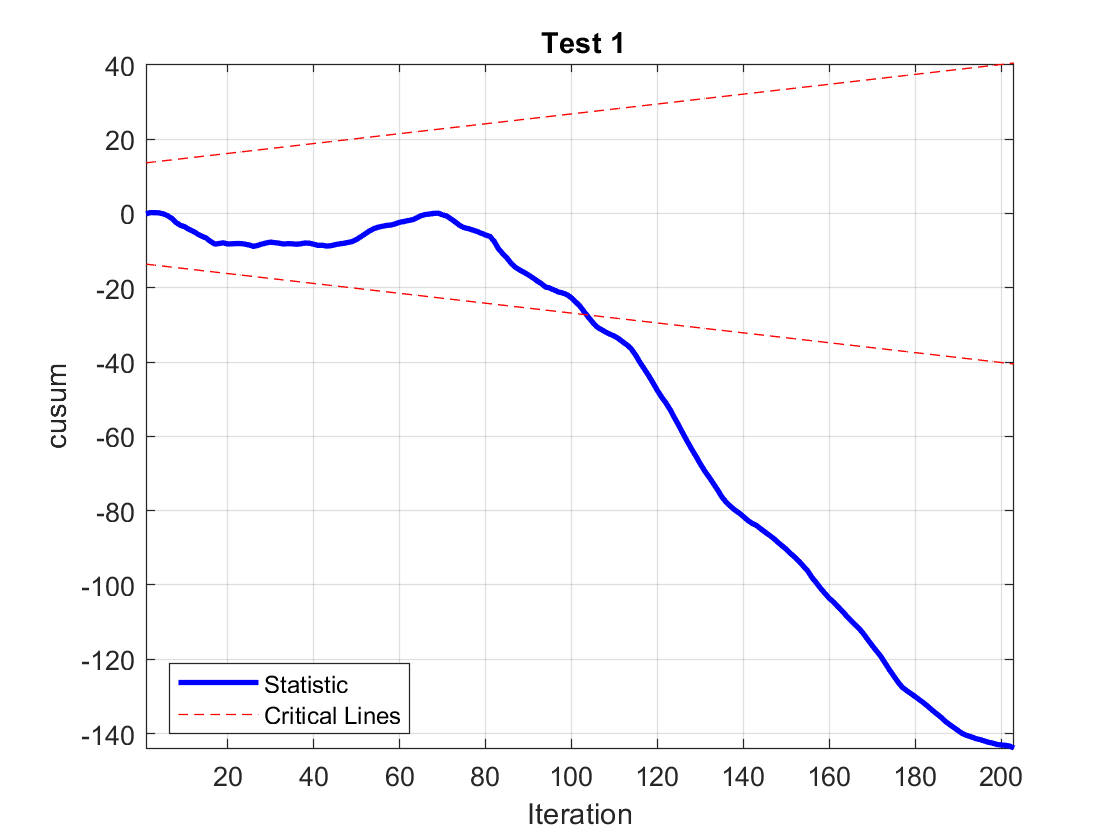

%   run the cusum test for the structural change of the intercept-only regression 
%   h -- 1 if constancy coefficients H0 holds;  0 otherwise;
%   H -- a 1x(T-k) sequence of test decisions (1 or 0) for all observations
%   starting from k+1
[h1,H1]=cusumtest(ones(length(us10y),1),us10y,'Test','cusum',...
    'Direction',{'forward'},'Alpha',0.05,'Intercept',false,'Plot','on');

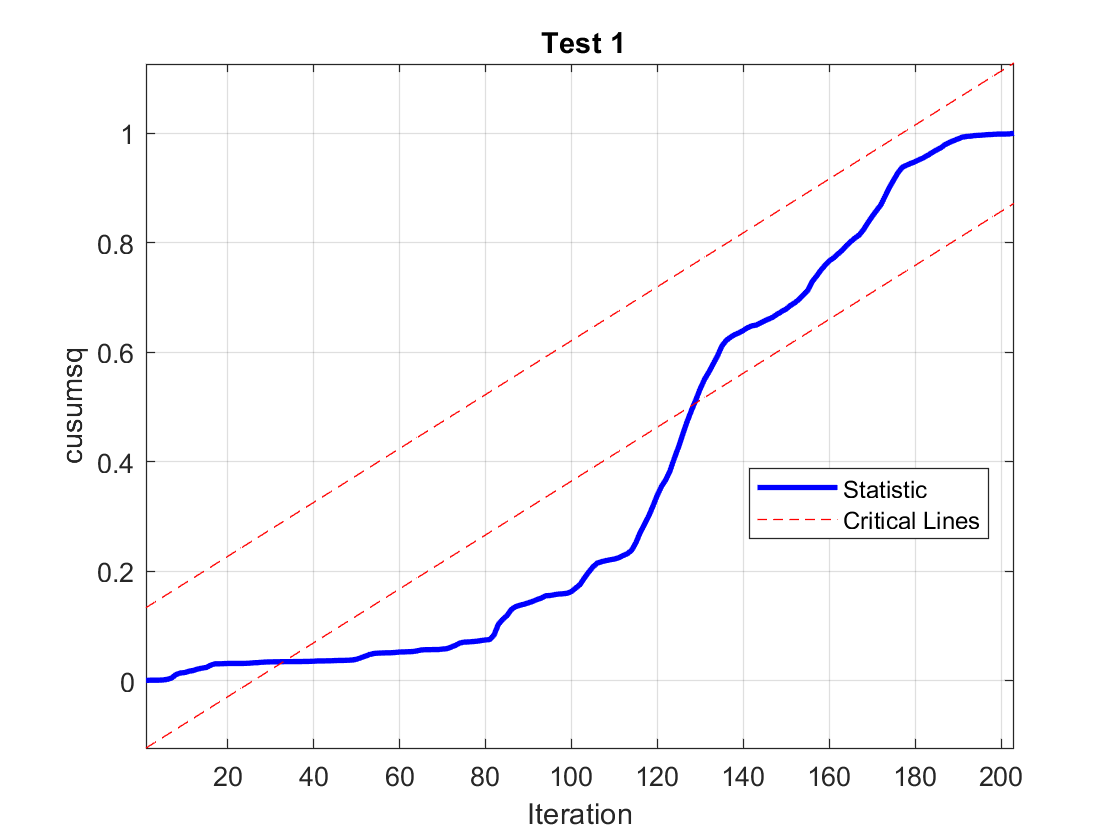

%   run the cusum square test (for volatility structural break)
[h2,H2]=cusumtest(ones(length(us10y),1),us10y,'Test','cusumsq',...
    'Direction',{'forward'},'Alpha',0.05,'Intercept',false,'Plot','on');

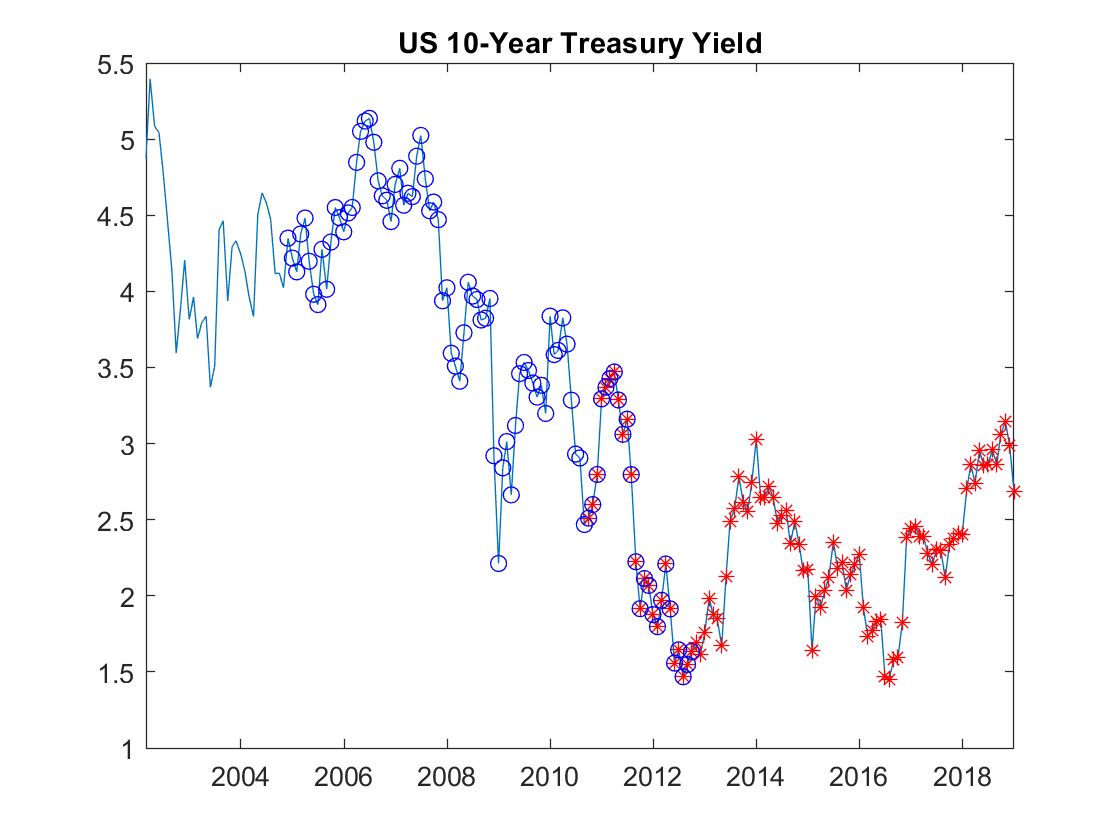

%   plot the historical yield movements
x_vec=datetime(datevec(tradays));
y_vec=us10y;

%   let's start from k+1, where k=1 because we only use one regressor
x_vec=x_vec(2:end);
y_vec=y_vec(2:end);
figure
plot(x_vec,y_vec)
title('US 10-Year Treasury Yield')
hold on 
plot(x_vec(H1),y_vec(H1),'*r');
hold on 
plot(x_vec(H2),y_vec(H2),'ob');